CiK = 155; %mM
CoK = 4;%mM
CiNa = 12; %mM
CoNa = 145; %mM
% CiCa = 10e-4;
% CoCa = 1.5;
CiCl = 4; %mM
CoCl = 120; %mM

Cm = 1; %uF/cm^2
gna = 100; %mS/cm^2
gk = 50; %mS/cm^2

Ek = 25/1*log(CoK/CiK); %mV
Ena = 25/1*log(CoNa/CiNa); %mV
Ecl = 25/(-1)*log(CoCl/CiCl); %mV

pk = 1.0;
pna = 0.04;
pcl = 0.45;

Vm = 25*log((pk*CoK + pna*CoNa + pcl*CiCl)/(pk*CiK + pna*CiNa +  pcl*CoCl))

Vm = -72.3406

[m, alpham, betam] = channels(Vm,0.182,0.124,9,-35,-35) %Na

m = 0.0226

alpham = 0.1090

betam = 4.7045

[h, alphah, betah] = channels(Vm,0.024,0.0091,5,-50, -75) %Na inhibition

h = 0.1529

alphah = 0.0062

betah = 0.0345

[n, alphan, betan] = channels(Vm,0.02,0.002,9,20,20) %k

n = 3.4991e-04

alphan = 6.4647e-05

betan = 0.1847

delT = 0.01; %timestep ms
t = 0;

% m(1:501) = m;
% n(1:501) = n
% h(1:501) = h
%Im = stimulus current
gl = 0.5; %ms/cm^2
El = -72.5; %mV
Im(1)= 0; %uA


alpha = 0

beta = 0

for i = [2:501] %time in ms
    if 5 < i <= 7
        Im(i) = 10; %uA
    else 
        Im(i) = 0; %uA
    end
    t(i) = (t(i-1)) +delT;
    Ina = gna *m(i-1)^3*h(i-1)*(Vm(i-1)-Ena);
    Ik = gk*n(i-1)^4*(Vm(i-1)-Ek);
    Il = gl*(Vm(i-1)-El);
    delVm = delT*(Im(i-1)-Ina-Ik-Il)/Cm;
    %delVm = delT*(Im(i-1)-Il)/Cm;
    Vm(i) = Vm(i-1)+delVm; 
    [~, alpham, betam] = channels(Vm(i-1),0.182,0.124,9,-35,-35);
    m(i) = m(i-1) + delT*alpham*(1-m(i-1))-betam*m(i-1);
    [~, alphah, betah] = channels(Vm(i-1),0.024,0.0091,5,-50, -75); 
    h(i) = h(i-1) + delT*alphah*(1-h(i-1))-betah*h(i-1);
    [~, alphan, betan] = channels(Vm(i-1),0.02,0.002,9,20,20);
    n(i) = n(i-1) + delT*alphan*(1-n(i-1))-betan*n(i-1);

end

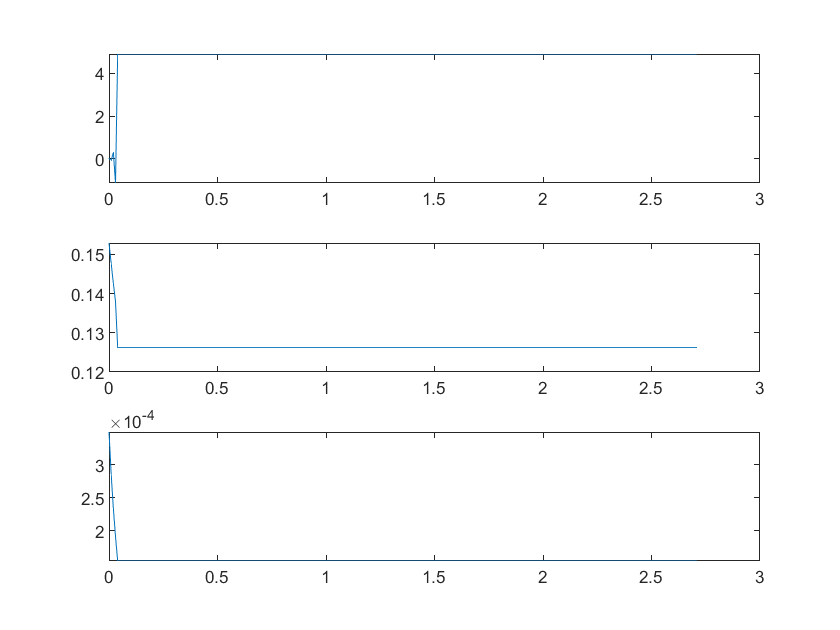


subplot(3,1,1)
plot(t,m)
subplot(3,1,2)
plot(t,h)
subplot(3,1,3)
plot(t,n)

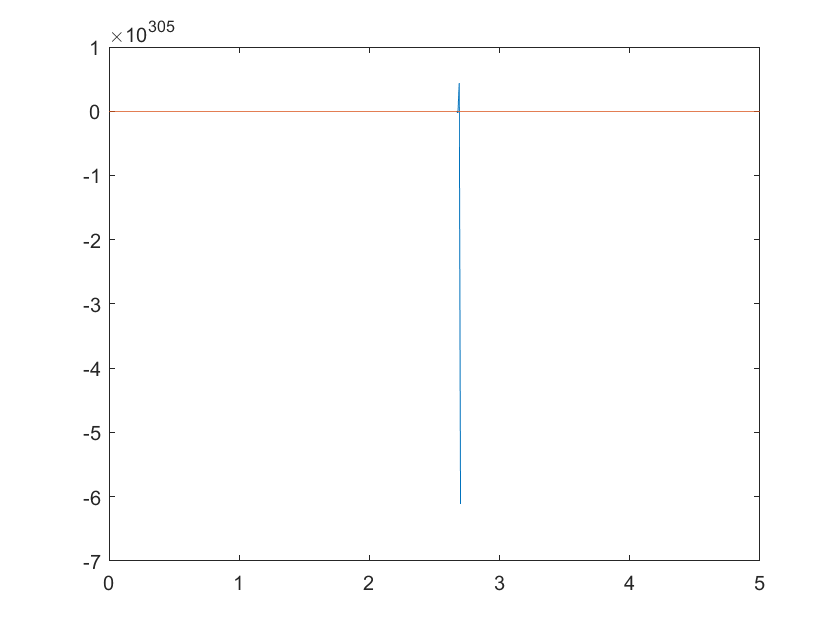

figure()
plot(t,Vm)
hold on
plot(t, Im)